
clc;
clear;
close all;

## Q1

Load the data and transpose the data.

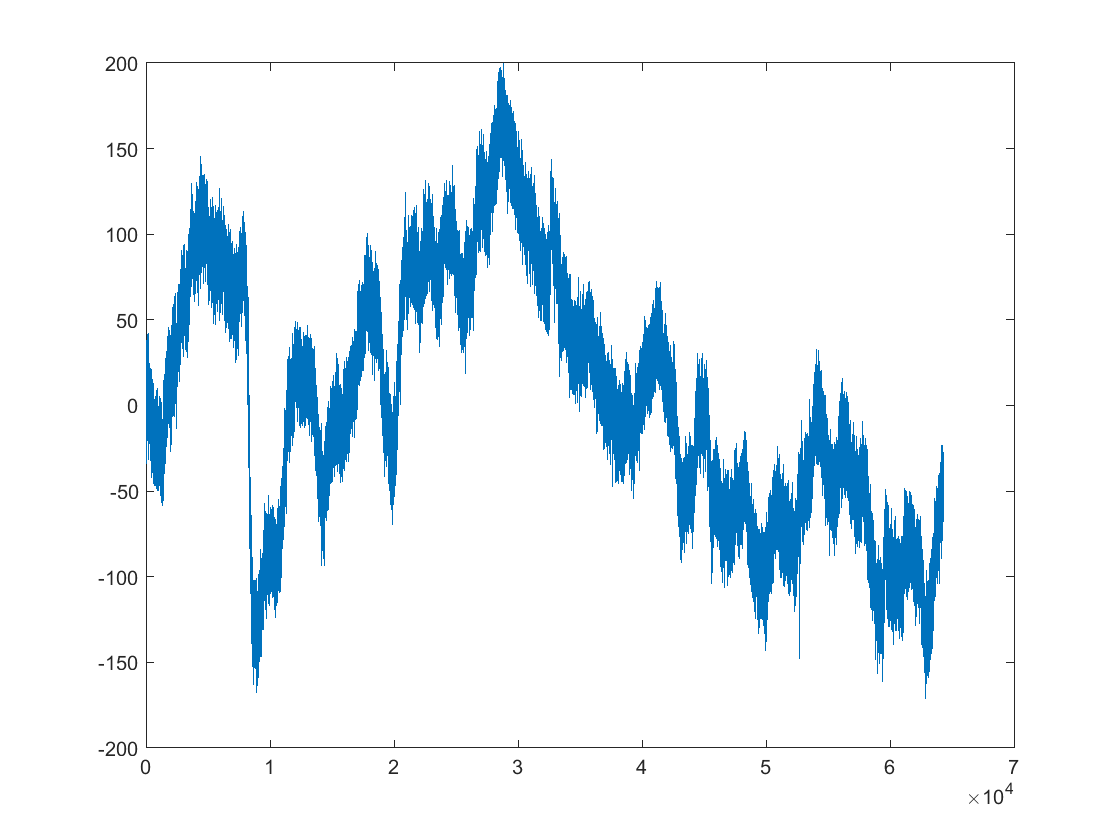

load("Subject1_1D.mat")

baseline = baseline';
left = left';
right = right';

plot(left(:,1))


electrodes = ["FP1", "FP2", "F3", "F4", "C3", "C4", "P3", "P4", "O1", "O2", "F7", "F8", "T3", "T4", "T5", "T6", "FZ", "CZ", "PZ"];
jb_test_output(1:19, 1:3) = 0

jb_test_output =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


for i=1:19
    jb_test_output(i, 1) = jbtest(baseline(:, i));
    jb_test_output(i, 2) = jbtest(left(:, i));
    jb_test_output(i, 3) = jbtest(right(:, i));
end
T = array2table(jb_test_output);
T.Properties.VariableNames(1:3) = {'Baseline','Left','Right'}

T = 19×3 table
    Baseline    Left    Right
    ________    ____    _____

       1         1        1  
       1         1        1  
       1         1        1  
       1         1        1  
       1         1        1  
       1         1        1  
       1         1        1  
       1         1        1  
       1         1        1  
       1         1        1  
       1         1        1  
       1         1        1  
       1         1        1  
       1         1        1  
       1         1        1  
       1         1        1  


T.Electrodes = electrodes'

T = 19×4 table
    Baseline    Left    Right    Electrodes
    ________    ____    _____    __________

       1         1        1        "FP1"   
       1         1        1        "FP2"   
       1         1        1        "F3"    
       1         1        1        "F4"    
       1         1        1        "C3"    
       1         1        1        "C4"    
       1         1        1        "P3"    
       1         1        1        "P4"    
       1         1        1        "O1"    
       1         1        1        "O2"    
       1         1        1        "F7"    
       1         1        1        "F8"    
       1         1        1        "T3"    
       1         1        1        "T4"    
       1         1        1        "T5"    
       1         1        1        "T6"    


All Jacque bera tests have a p value less than 0.05 (the test returns 1 when the null hypothesis is rejected) therefore, we reject the null hypothesis and we know that the data is not normally distributed.

Create the boxplots.

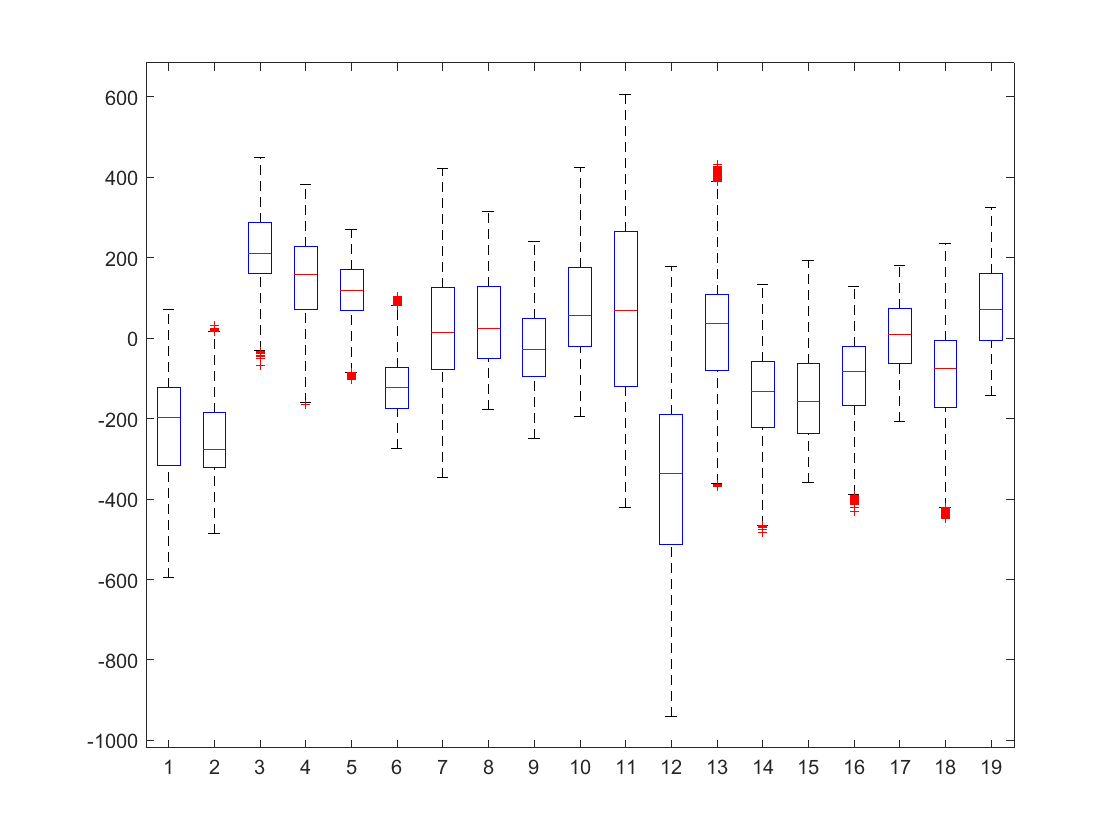

boxplot(baseline)

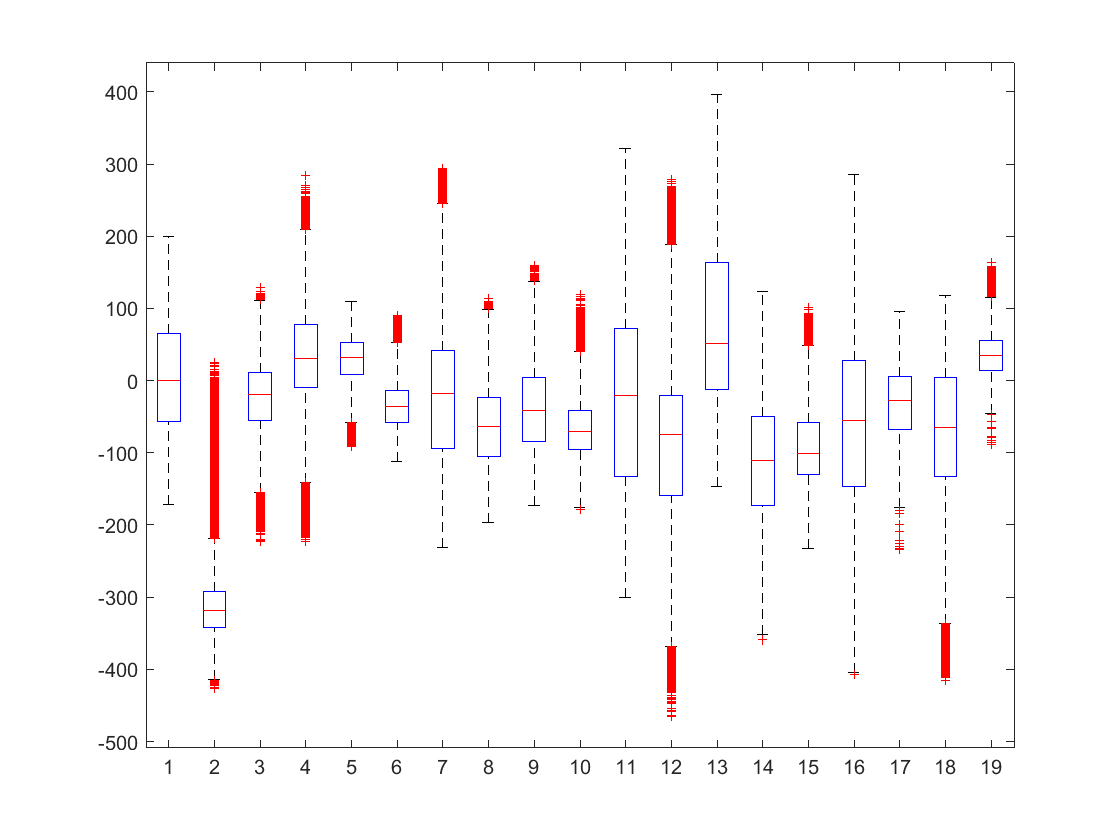

boxplot(left)

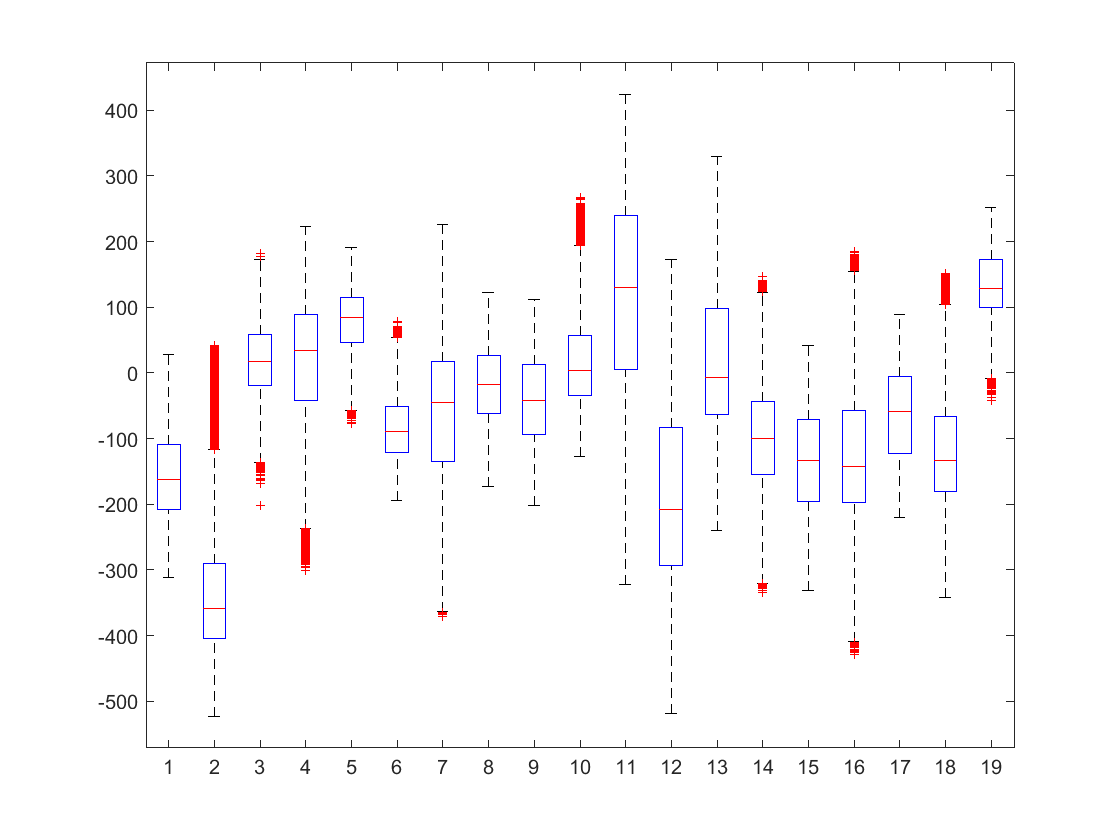

boxplot(right)

Electrode 2 based on the boxplots has the most prominent outliers.

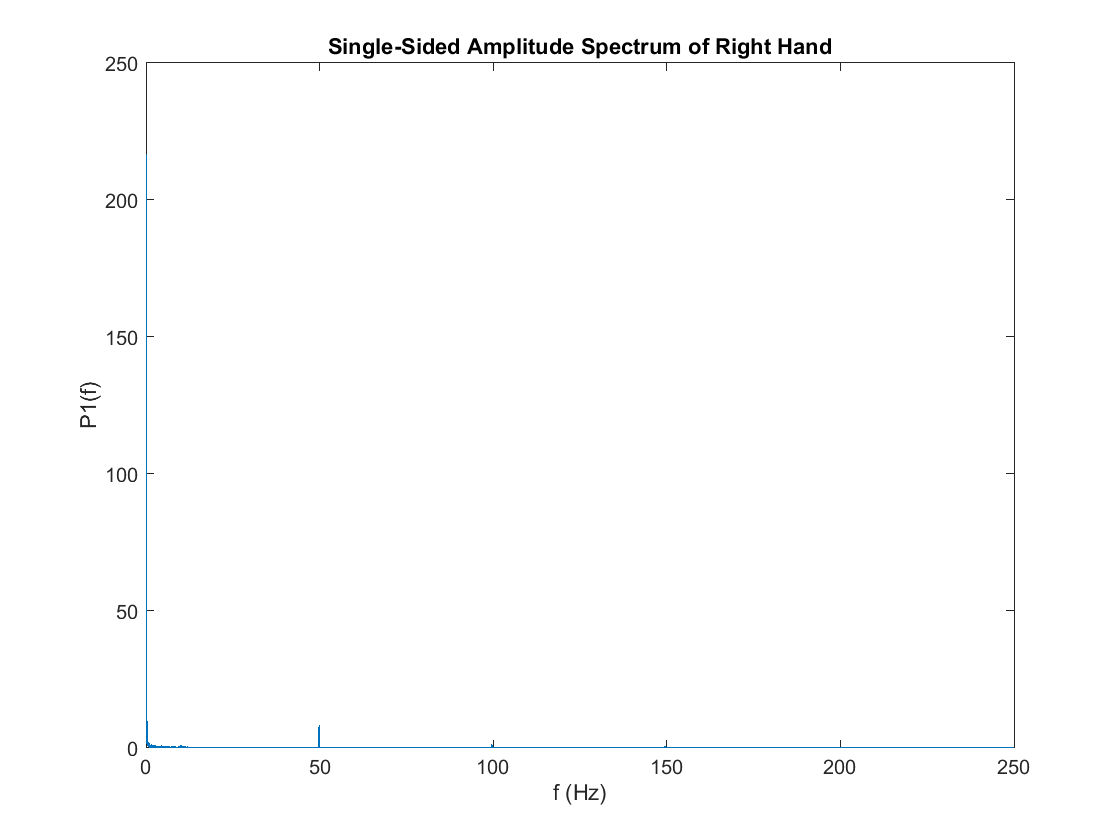

Fs = 500;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 64300;             % Length of signal
t = (0:L-1)*T;

filter_spec = designfilt('lowpassiir','FilterOrder',3, ...
    'HalfPowerFrequency',0.1,'DesignMethod','butter');

X = fft(baseline);
P2 = abs(X/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
figure,
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of Right Hand')
xlabel('f (Hz)')
ylabel('P1(f)')

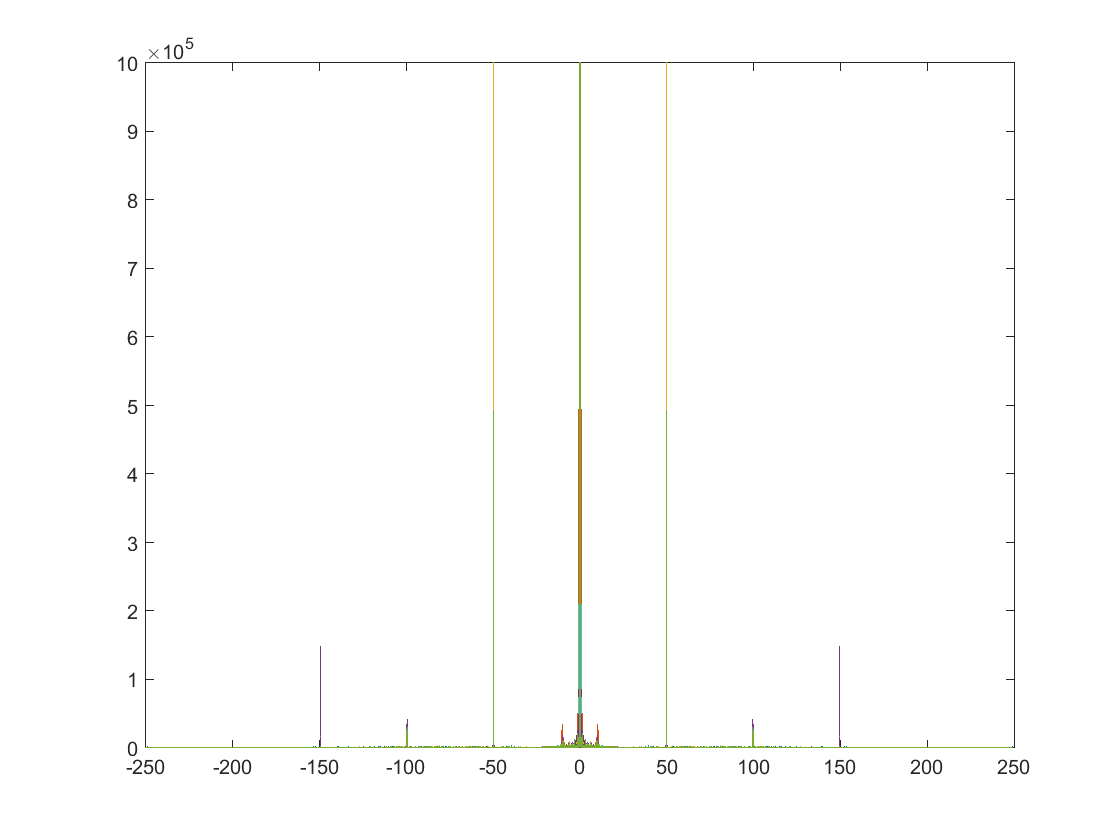


X = fftshift(X);
fshift = (-L/2:L/2-1)*(Fs/L); % zero-centered frequency range
powershift = abs(X).^2/L;     % zero-centered power
plot(fshift,powershift)
xlim([-250, 250])
ylim([0, 1000000])

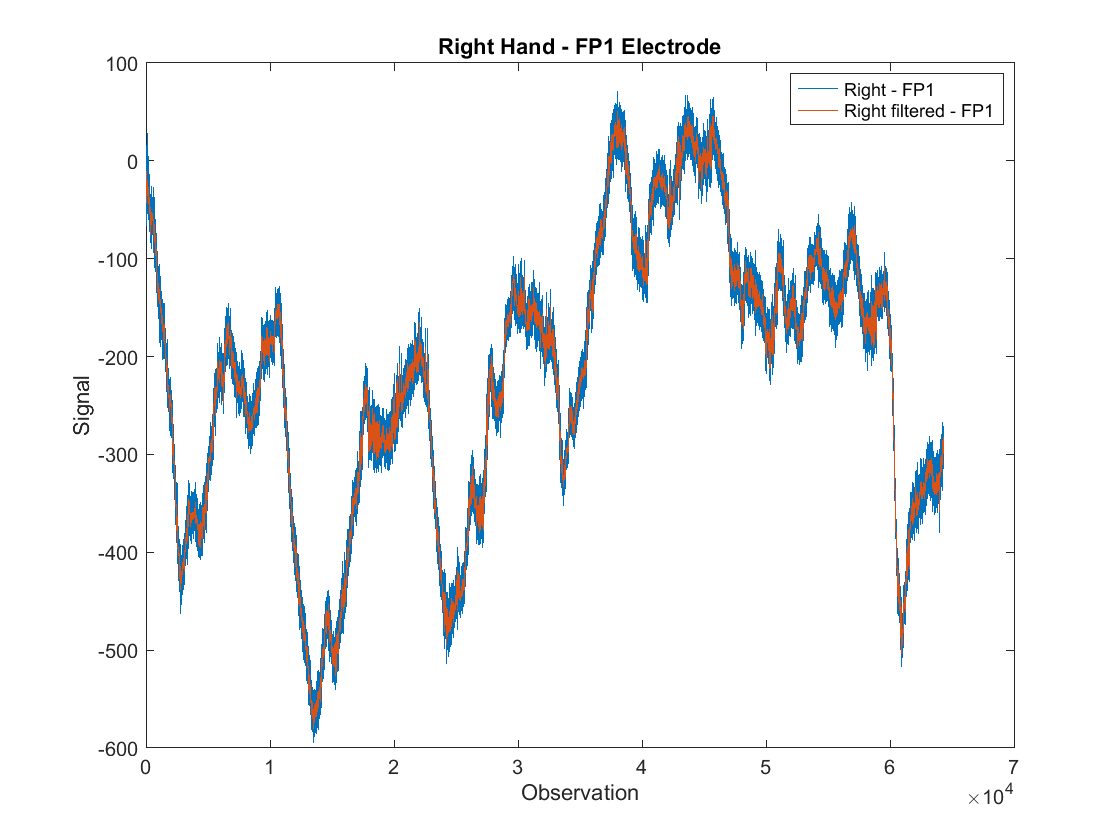

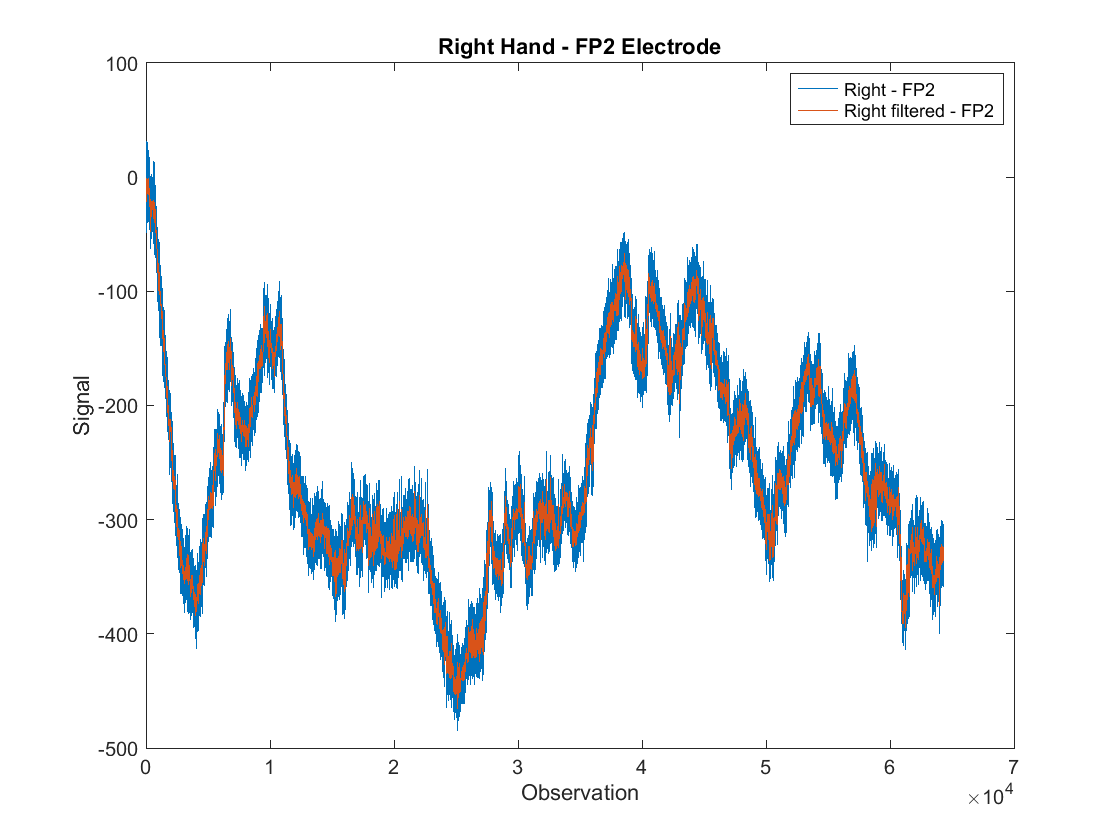

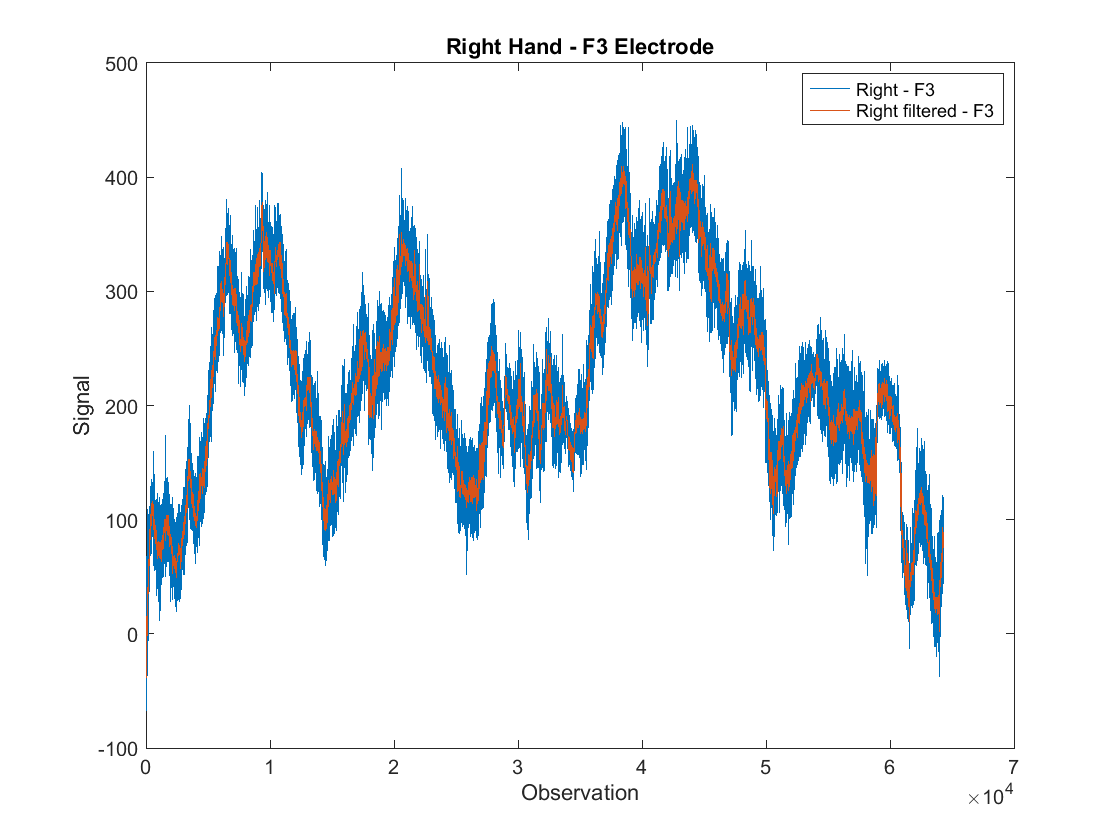

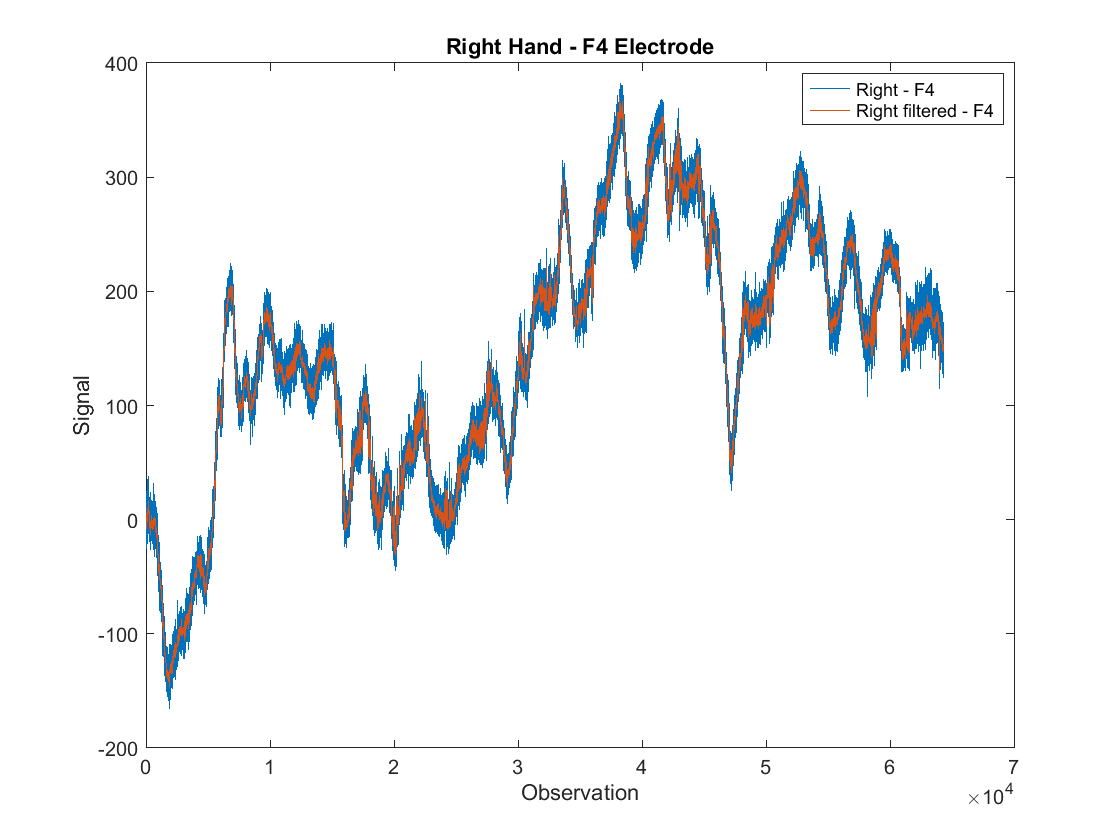

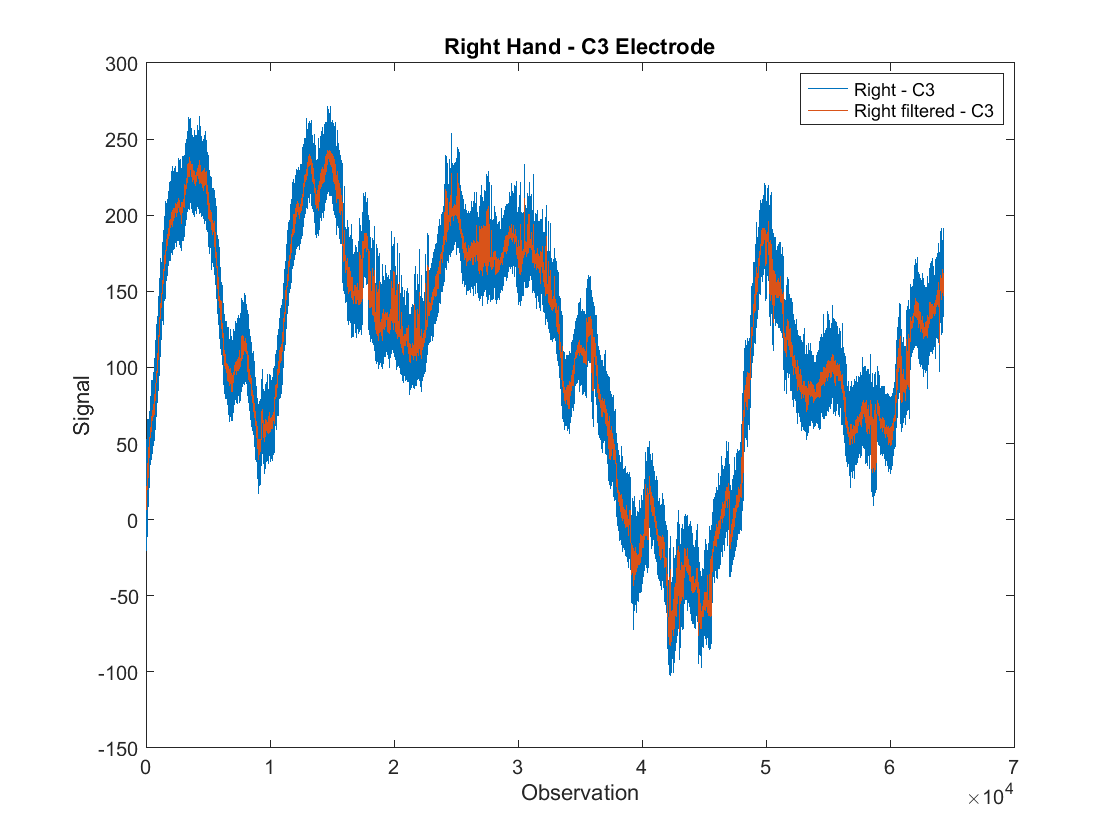

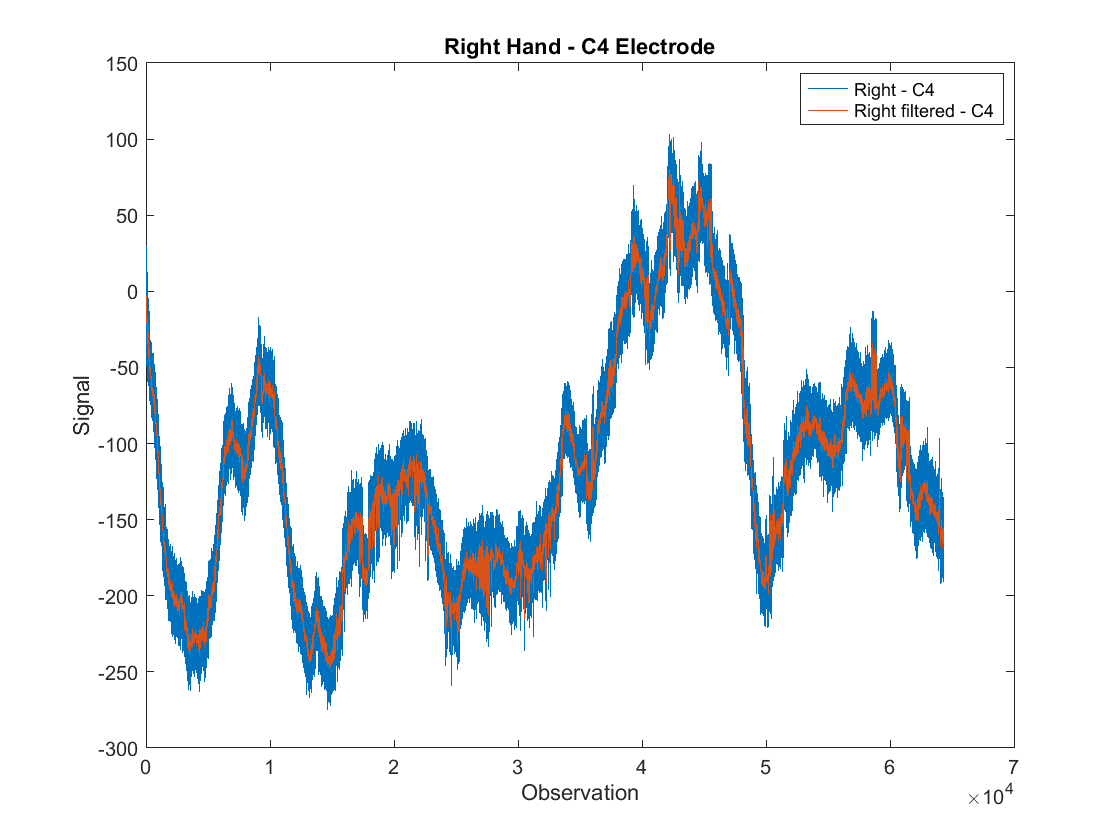

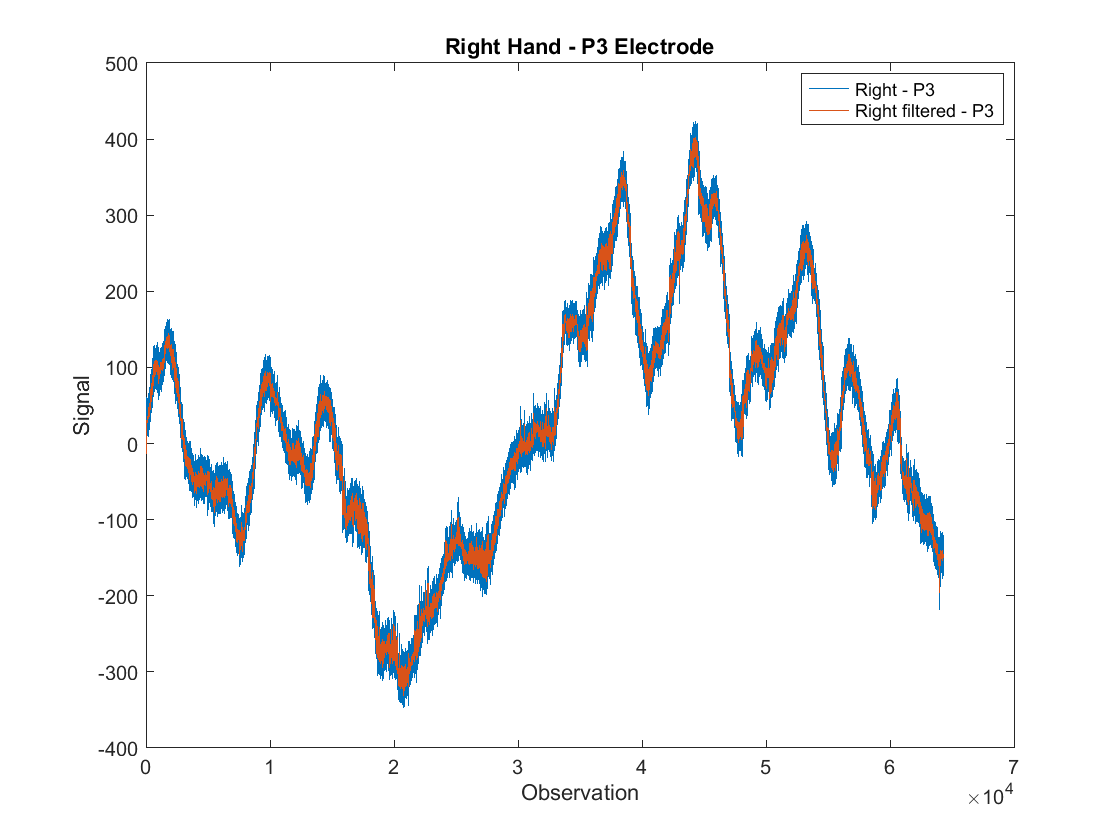

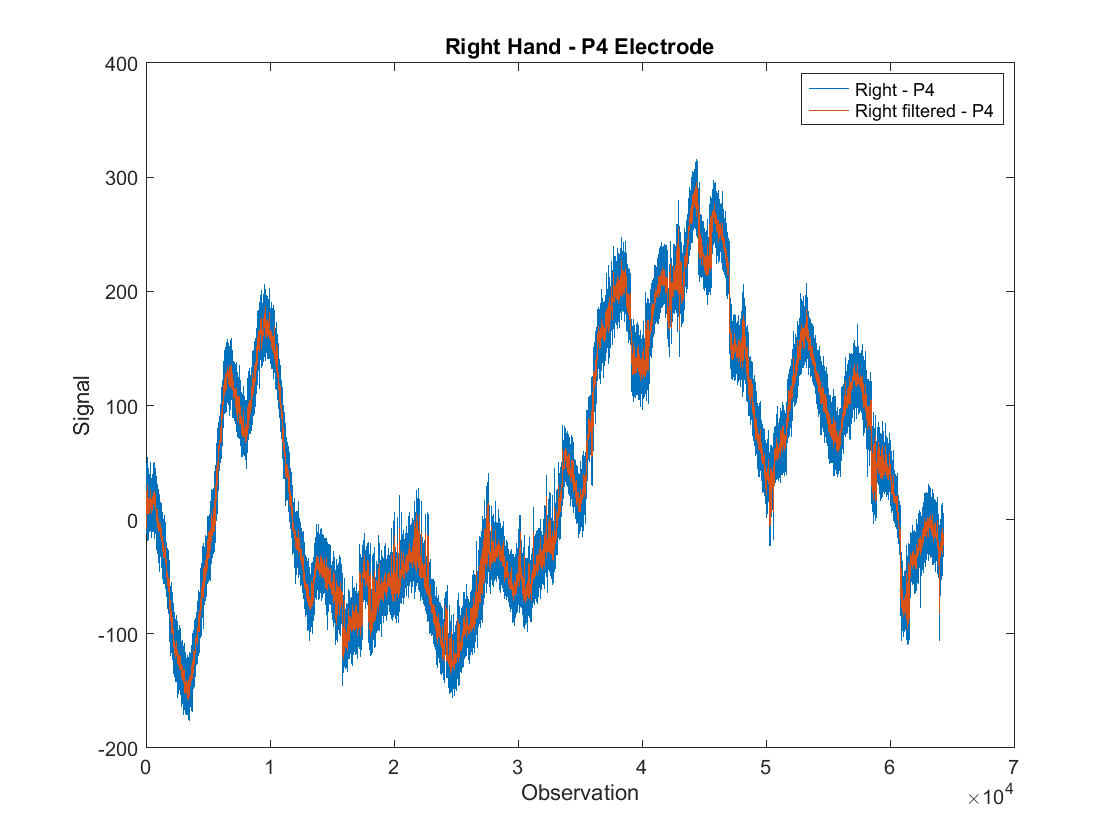

data = filtfilt(filter_spec, baseline);


for i=1:19
    figure
    plot(1:length(baseline(:, i)), baseline(:, i), 1:length(data(:,i)), data(:, i))
    xlabel("Observation")
    ylabel("Signal")
    legend(sprintf("Right - %s", electrodes(i)), sprintf("Right filtered - %s", electrodes(i)))
    title(sprintf("Right Hand - %s Electrode", electrodes(i)))
end

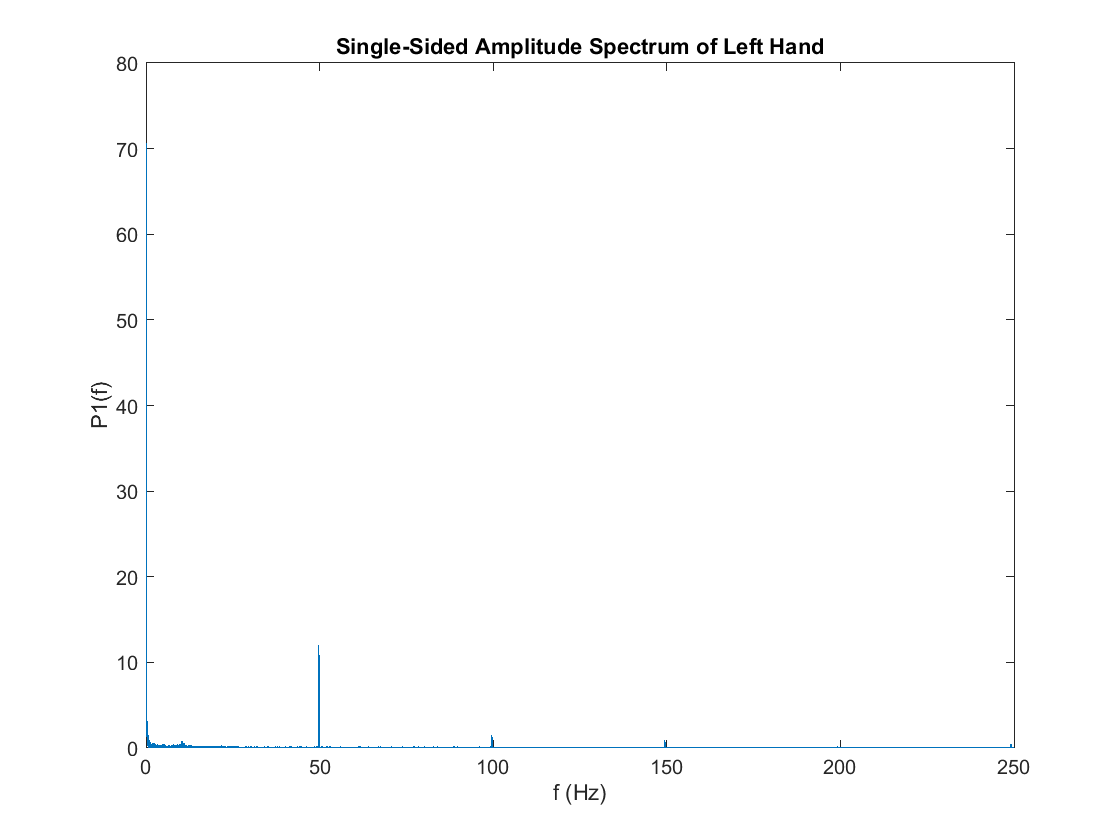

X = fft(left);
P2 = abs(X/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
figure,
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of Left Hand')
xlabel('f (Hz)')
ylabel('P1(f)')

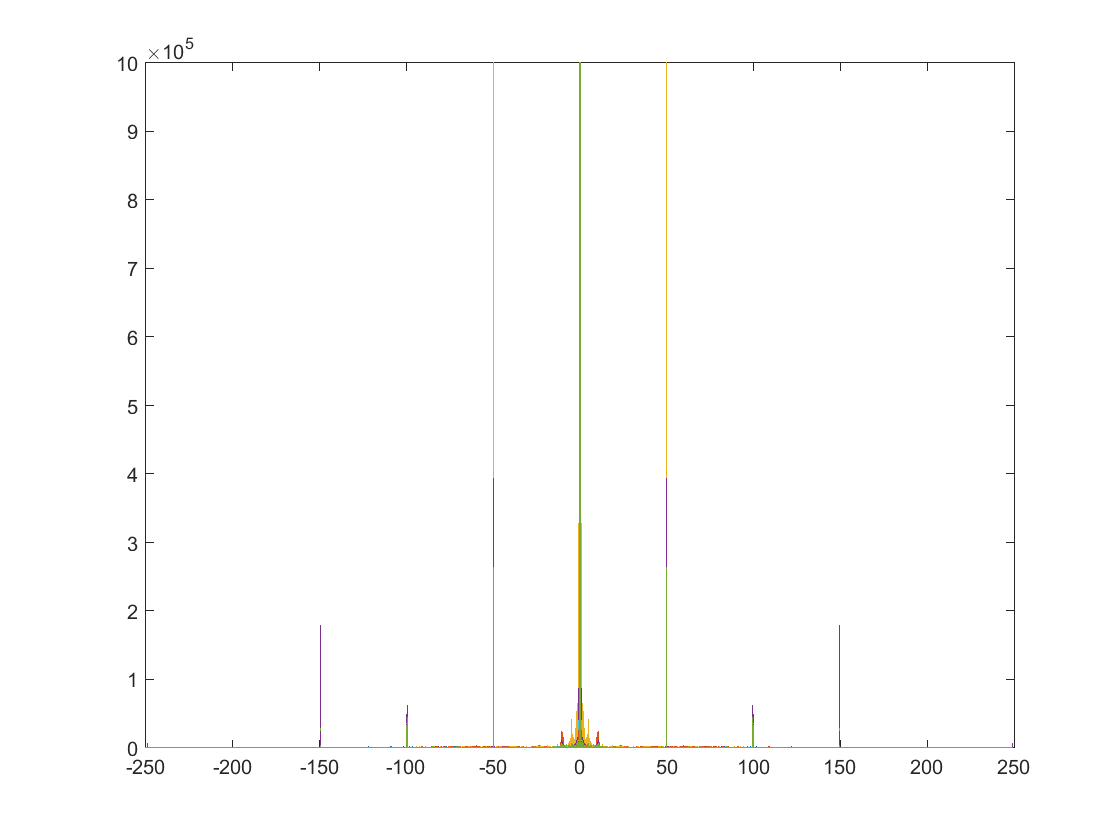


X = fftshift(X);
fshift = (-L/2:L/2-1)*(Fs/L); % zero-centered frequency range
powershift = abs(X).^2/L;     % zero-centered power
plot(fshift,powershift)
xlim([-250, 250])
ylim([0, 1000000])

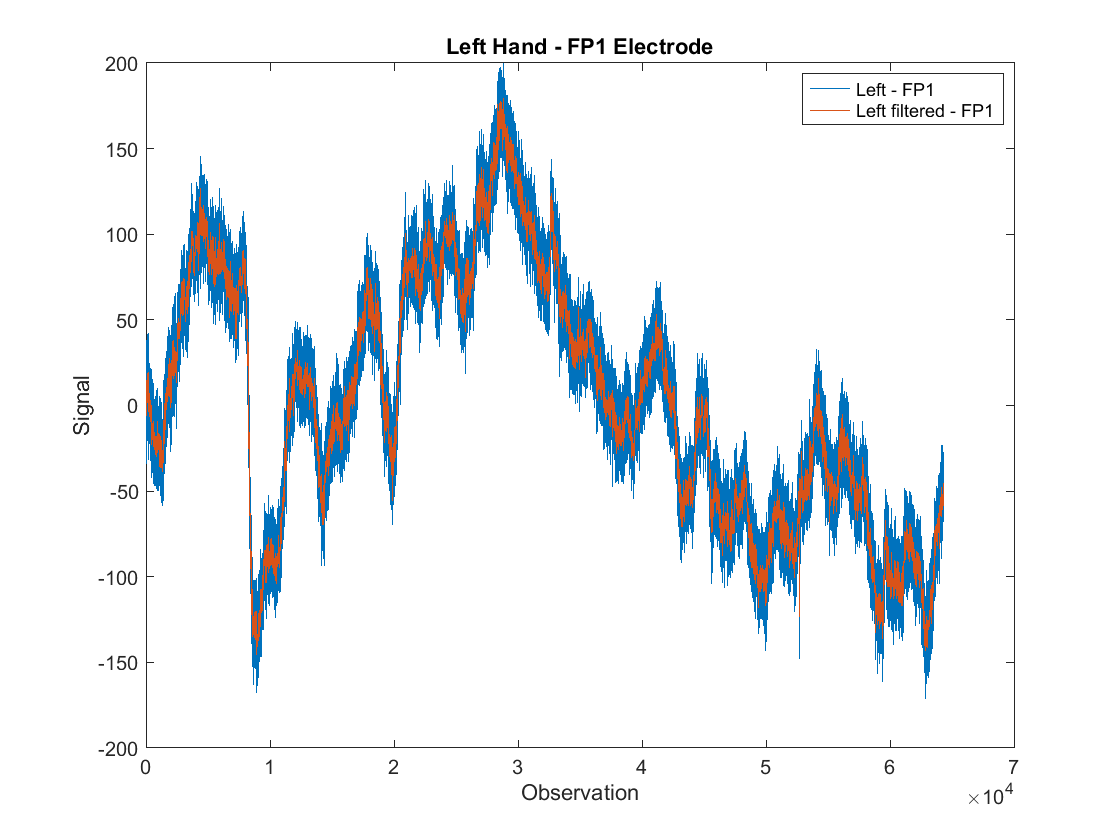

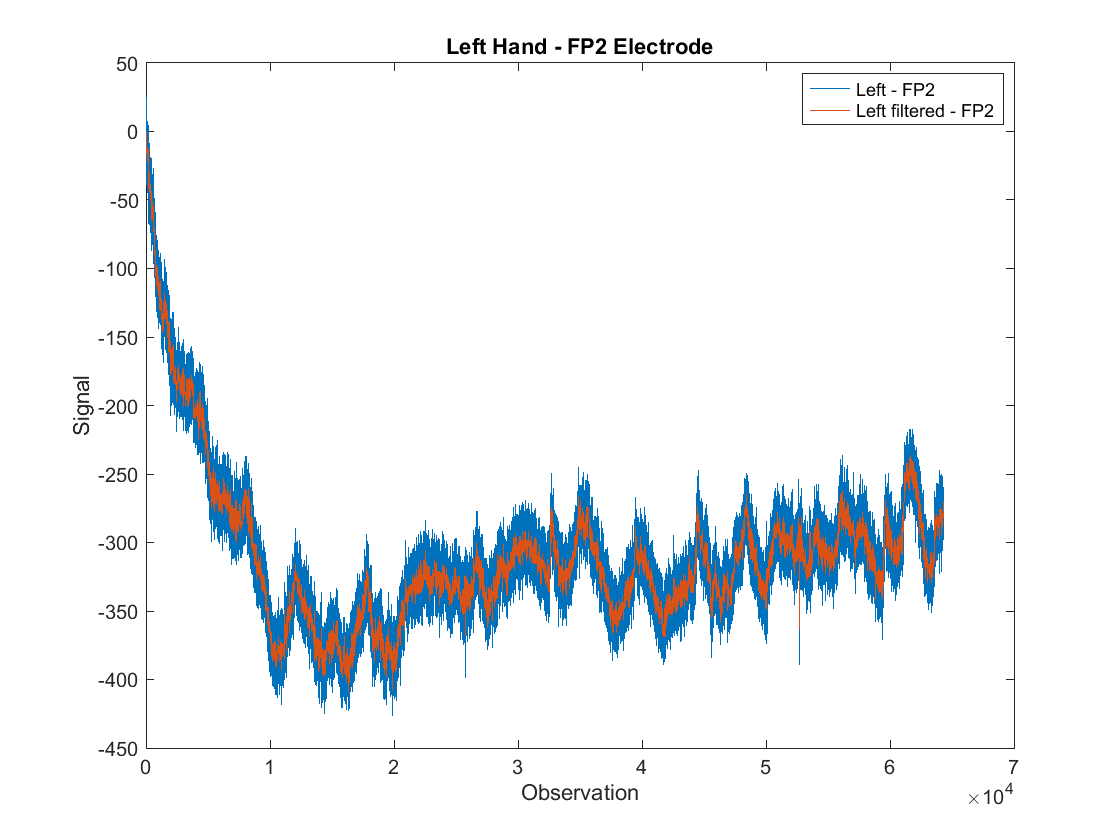

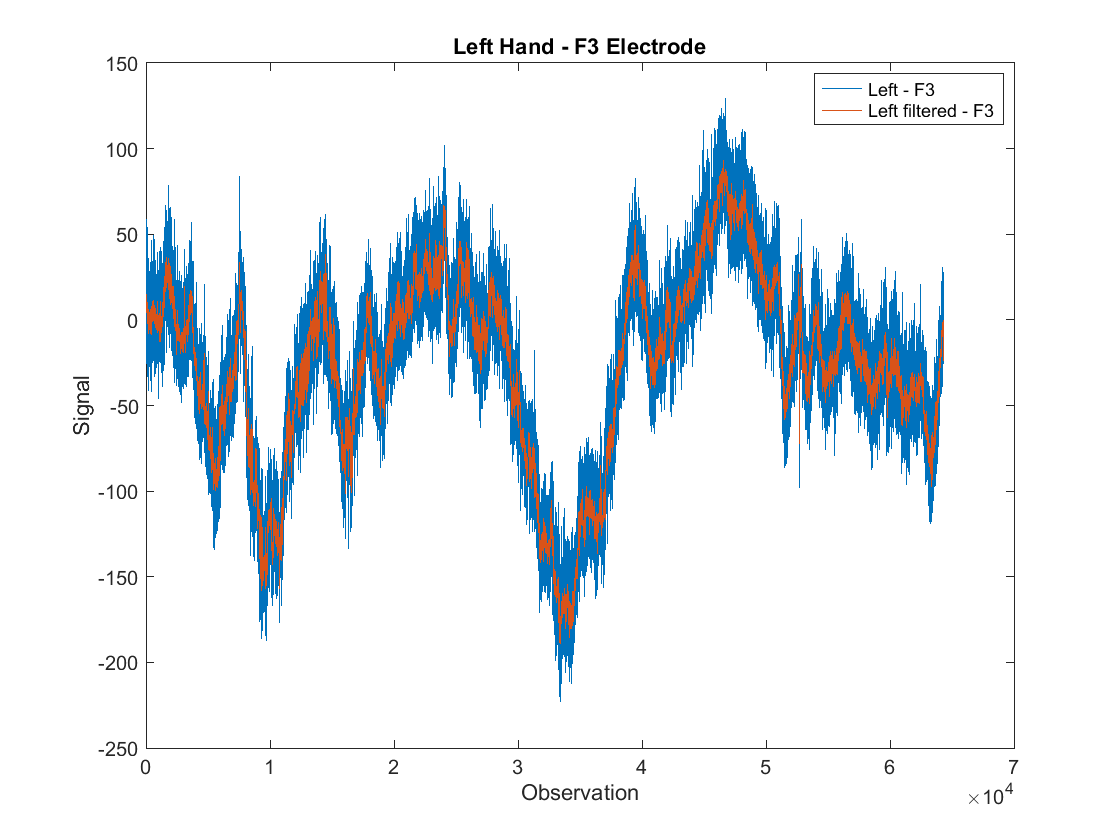

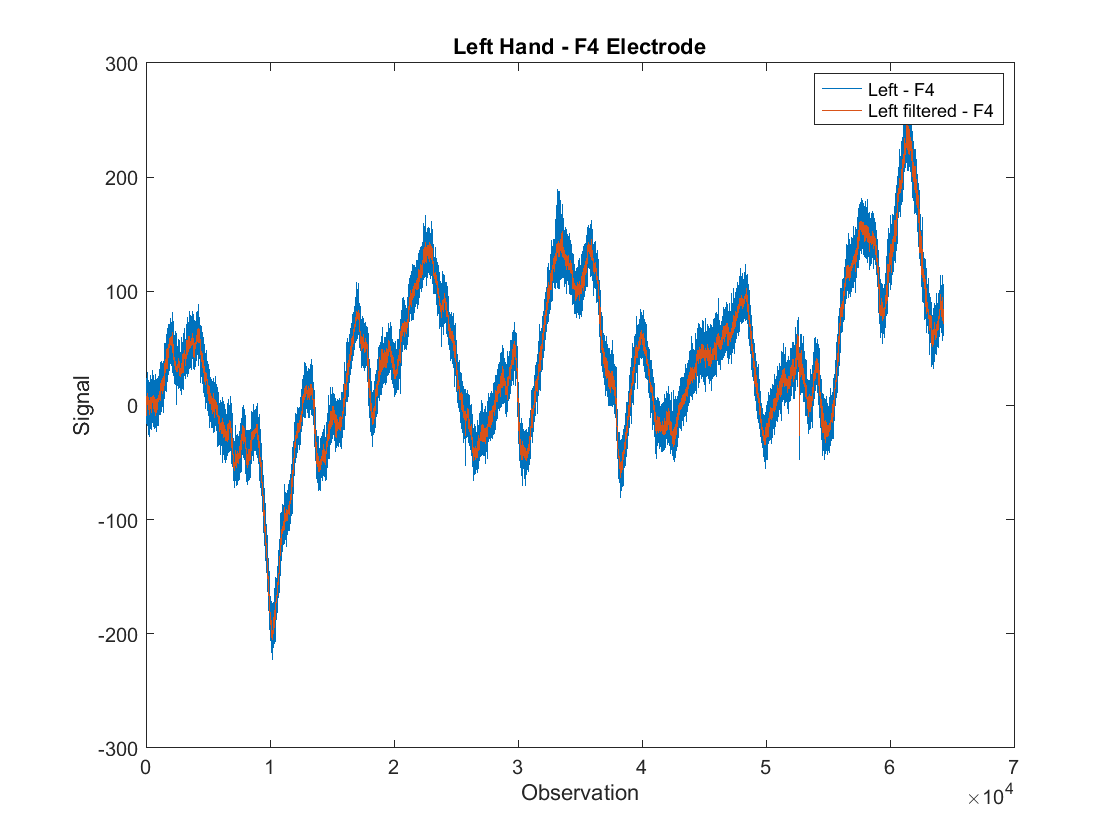

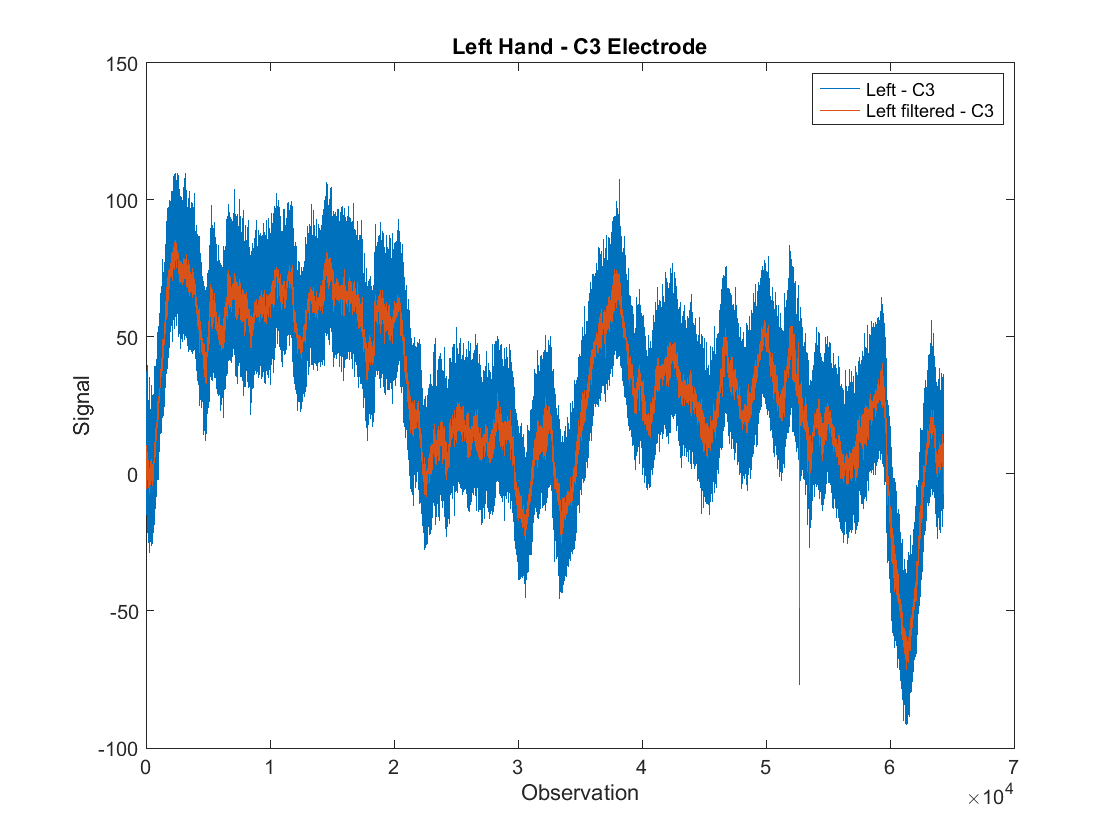

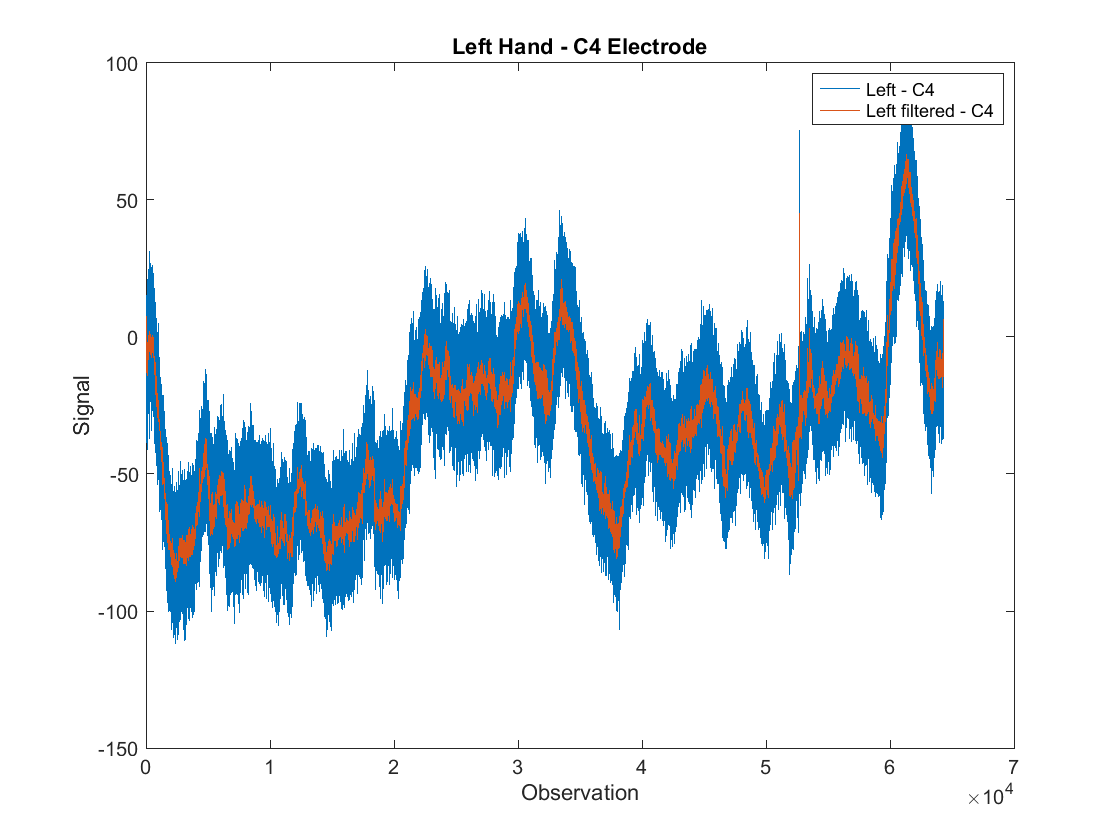

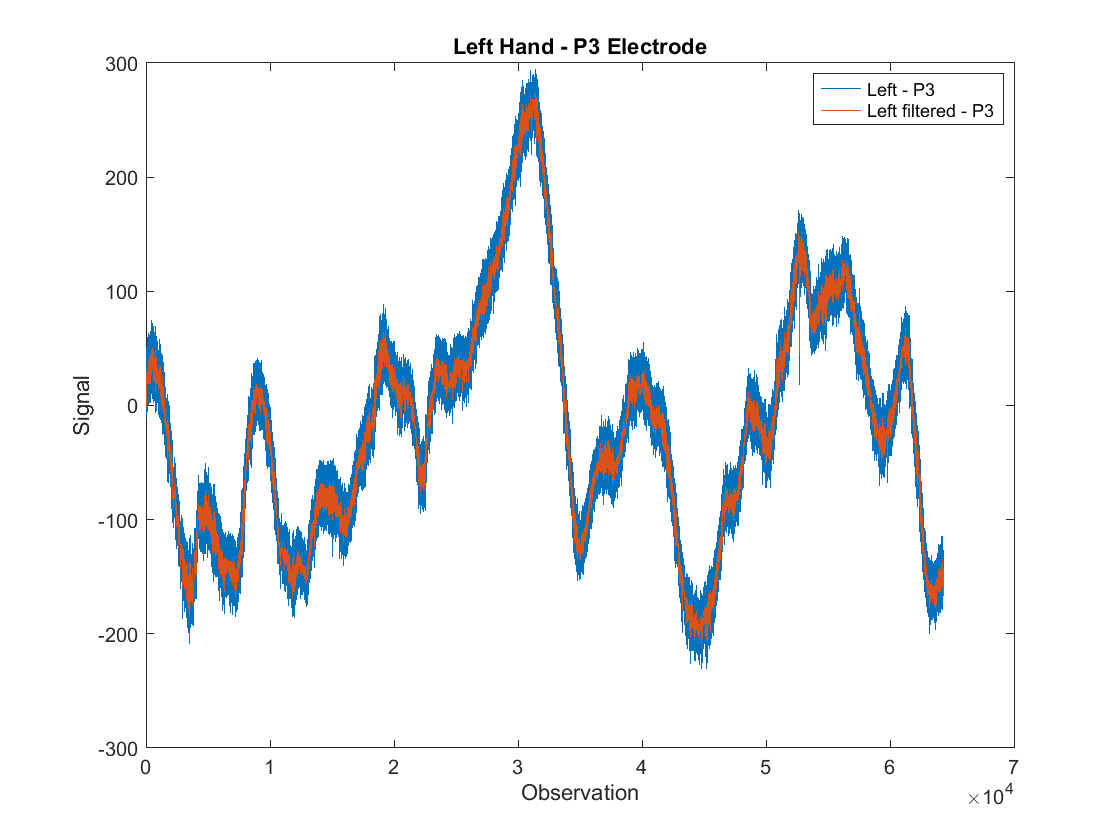

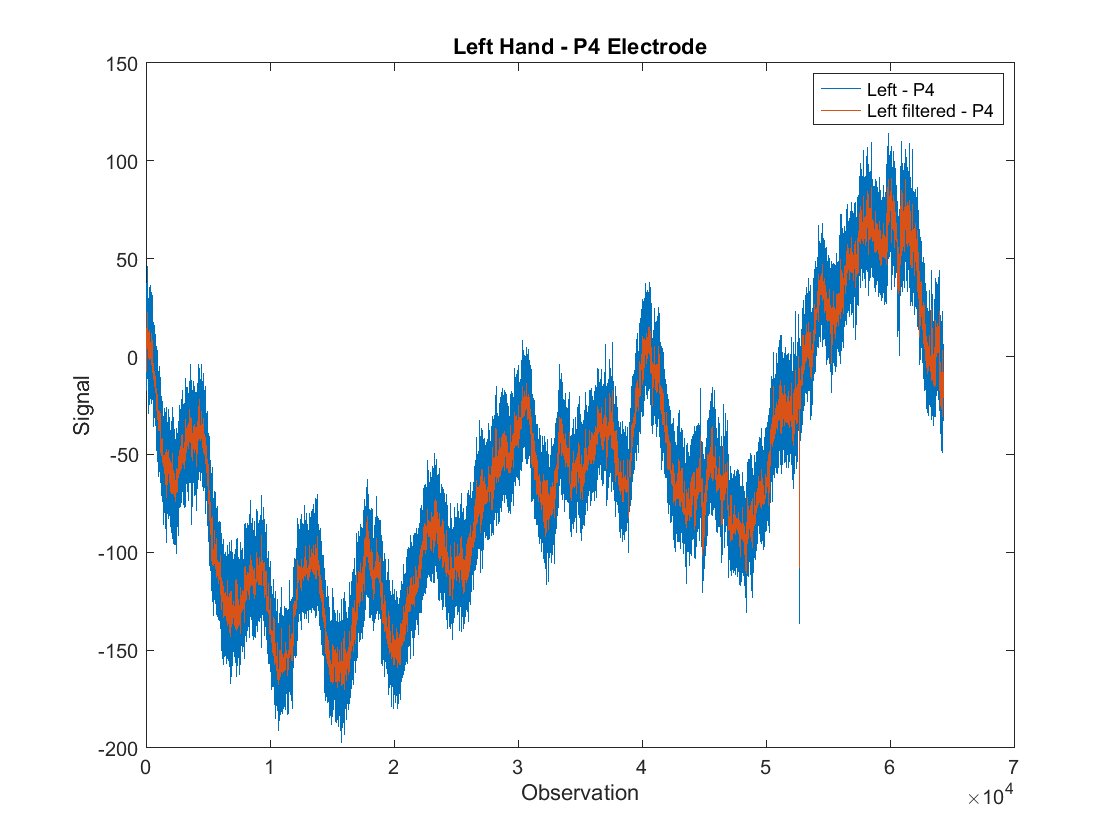

data = filtfilt(filter_spec, left);


for i=1:19
    figure
    plot(1:length(left(:, i)), left(:, i), 1:length(data(:,i)), data(:, i))
    xlabel("Observation")
    ylabel("Signal")
    legend(sprintf("Left - %s", electrodes(i)), sprintf("Left filtered - %s", electrodes(i)))
    title(sprintf("Left Hand - %s Electrode", electrodes(i)))
end

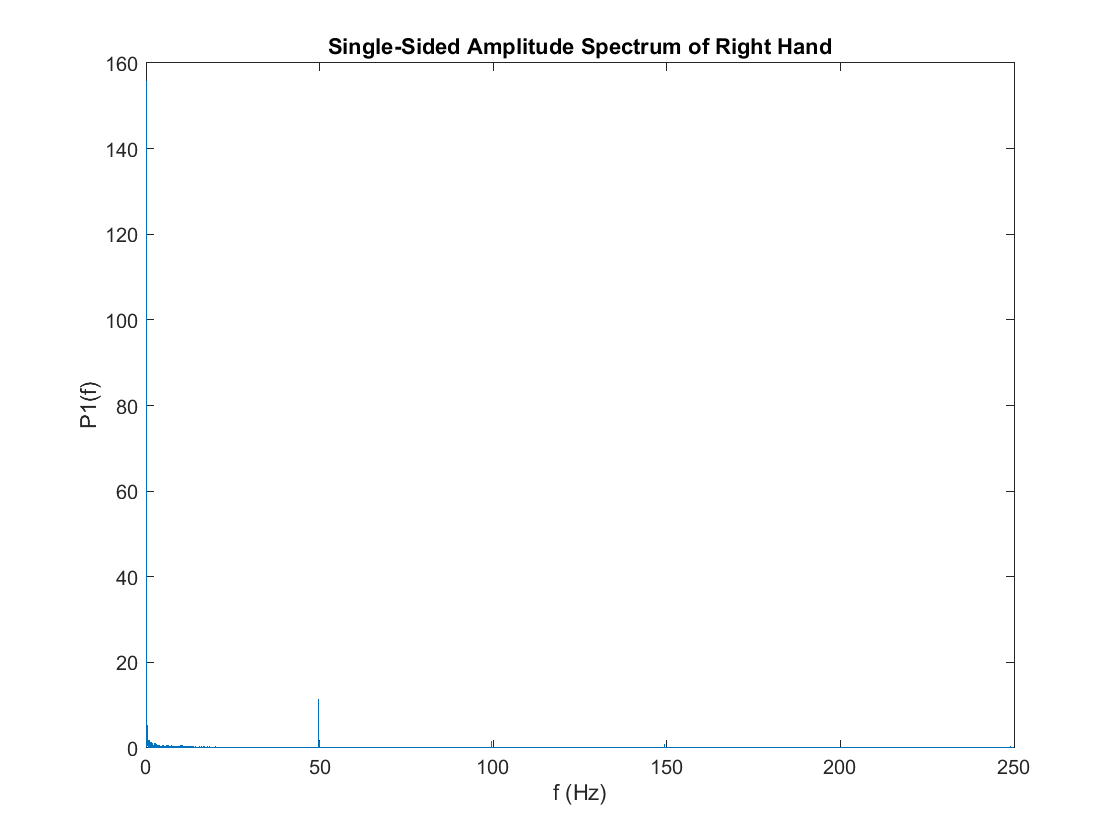

X = fft(right);
P2 = abs(X/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
figure,
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of Right Hand')
xlabel('f (Hz)')
ylabel('P1(f)')

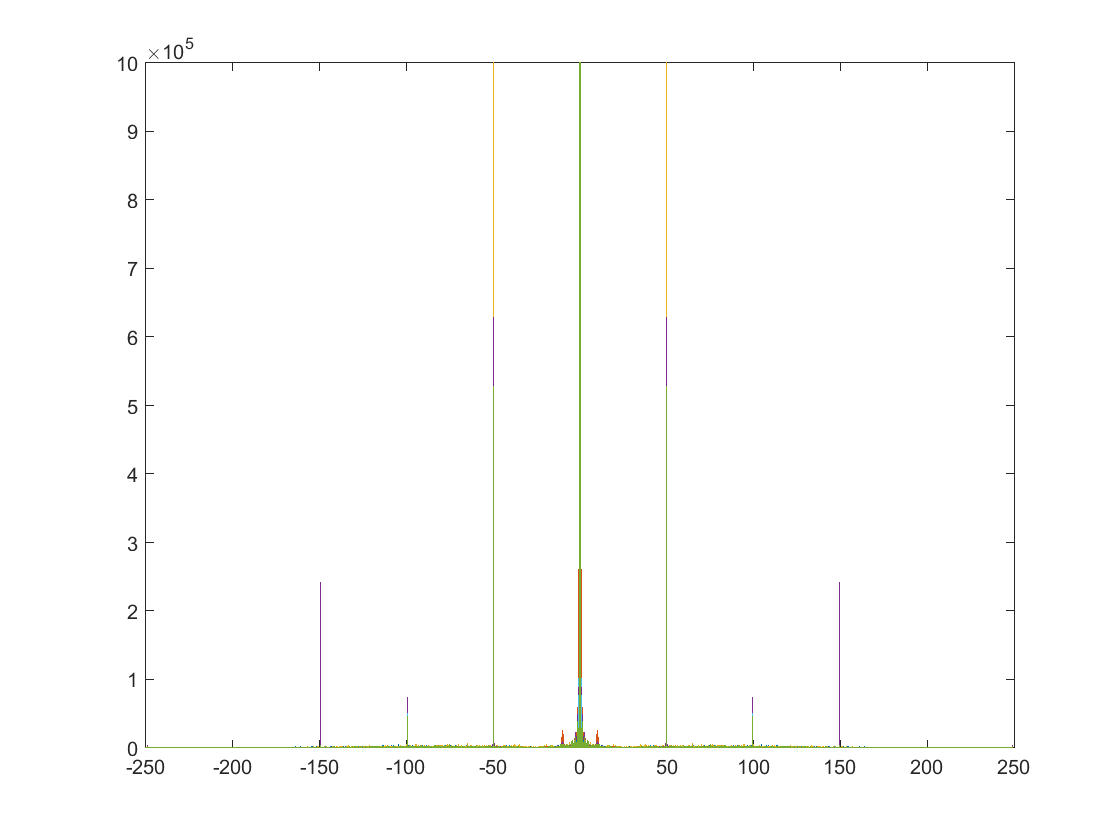


X = fftshift(X);
fshift = (-L/2:L/2-1)*(Fs/L); % zero-centered frequency range
powershift = abs(X).^2/L;     % zero-centered power
plot(fshift,powershift)
xlim([-250, 250])
ylim([0, 1000000])

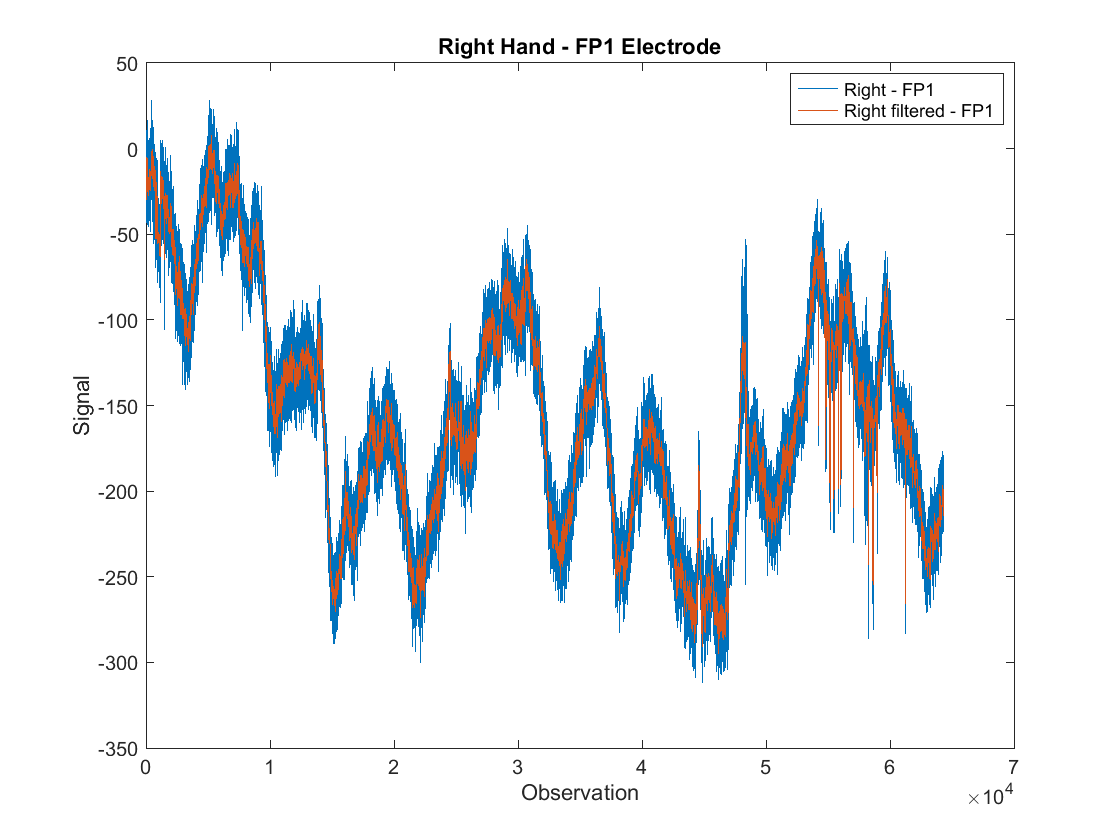

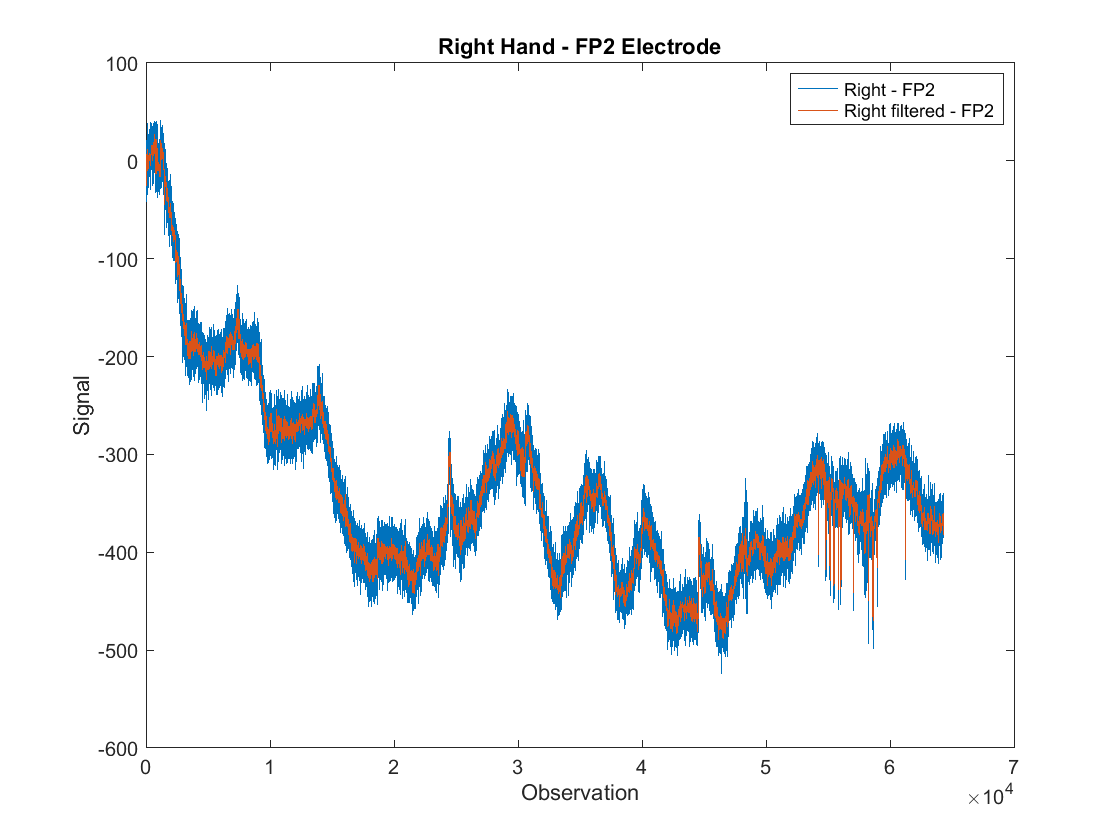

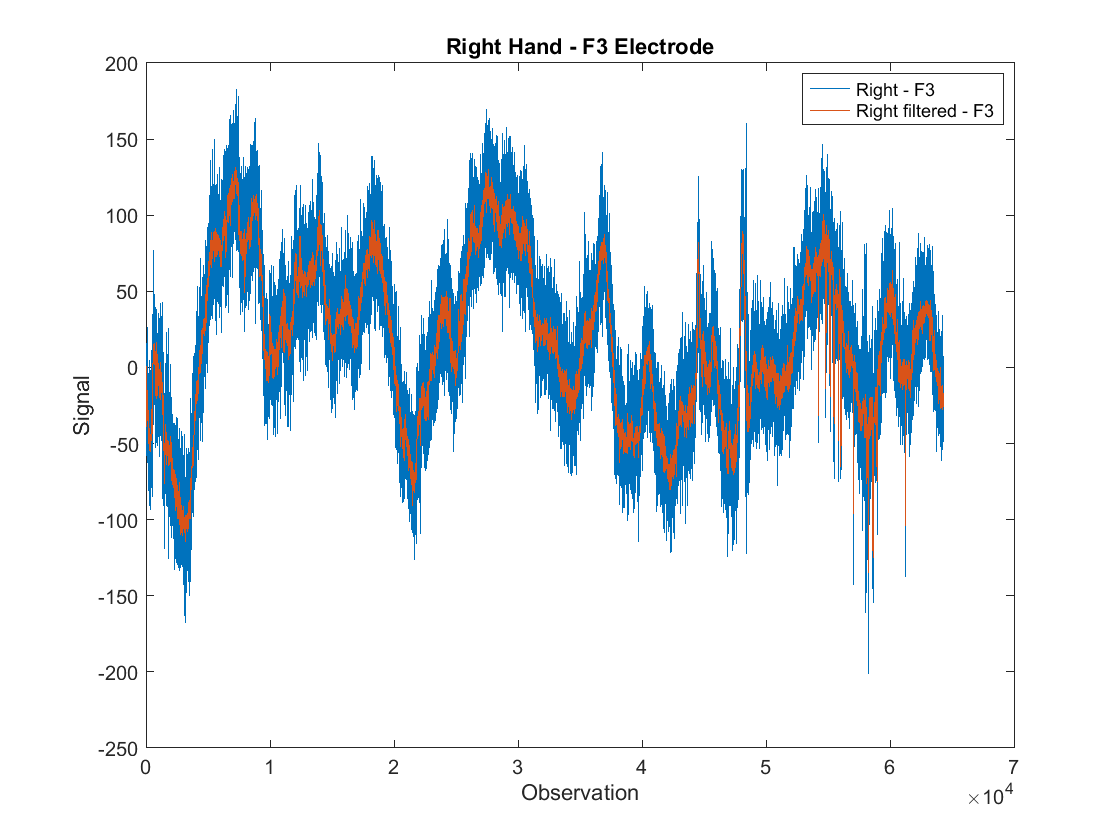

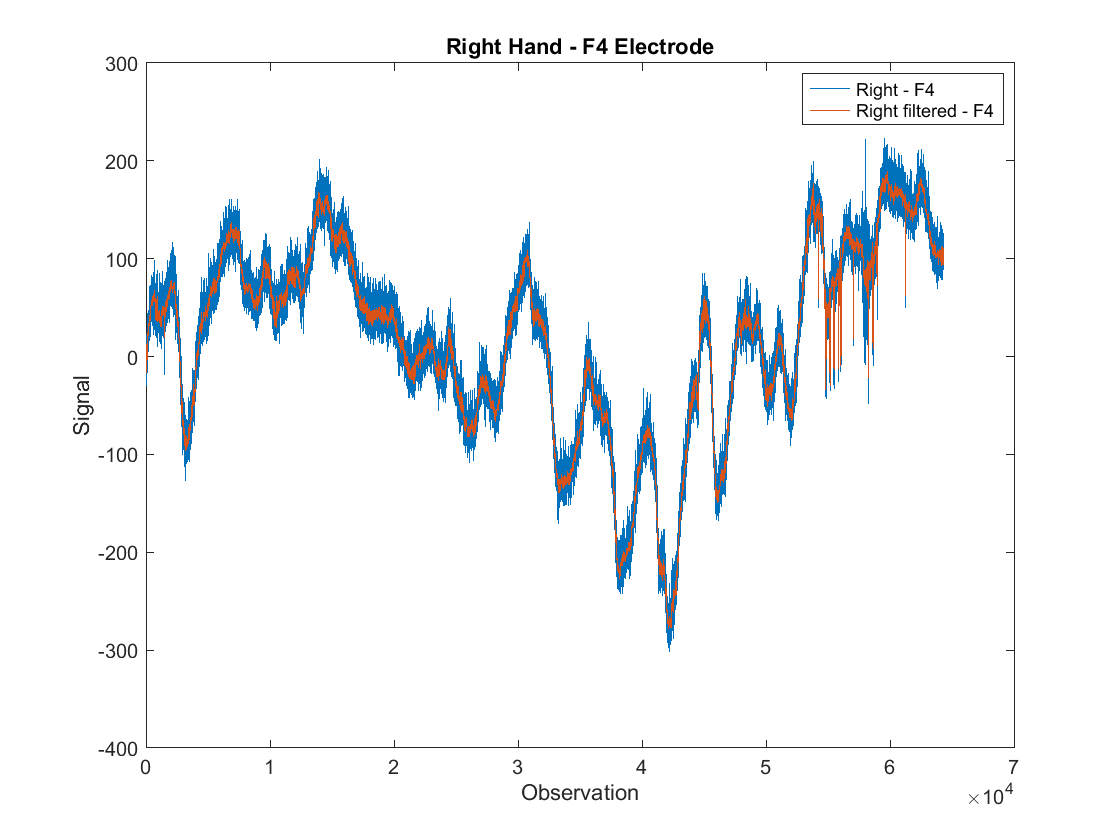

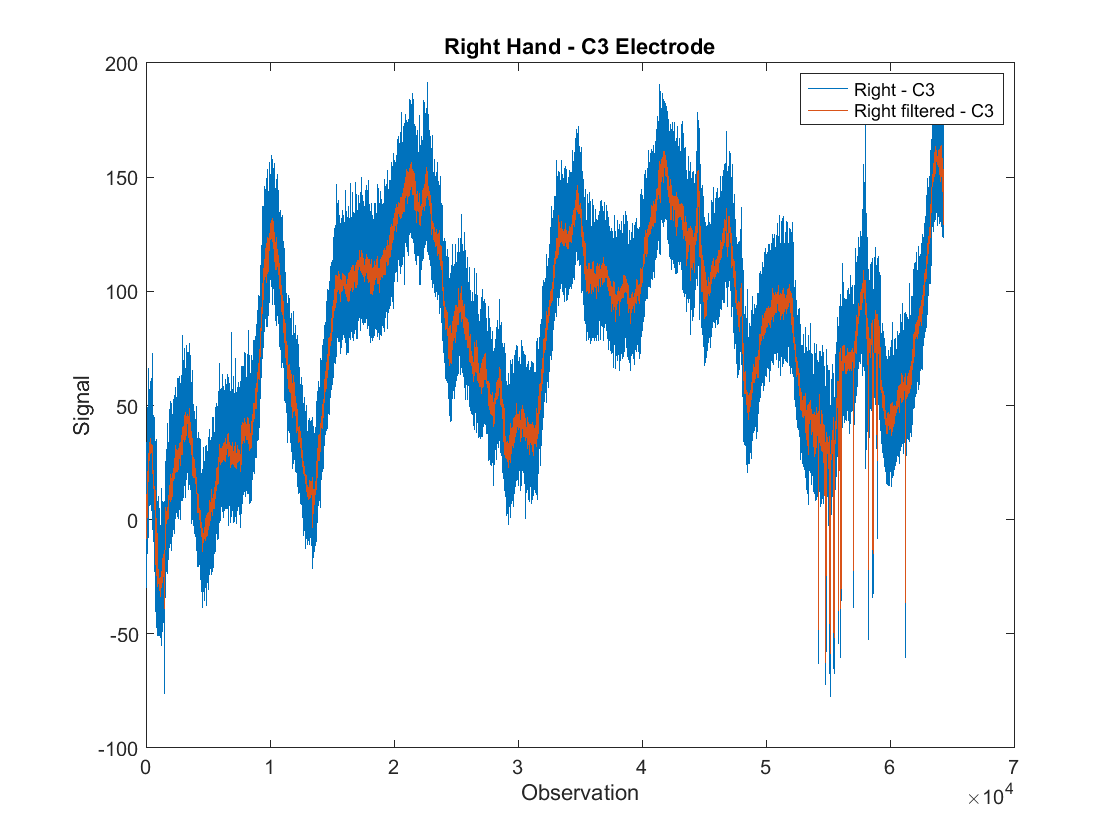

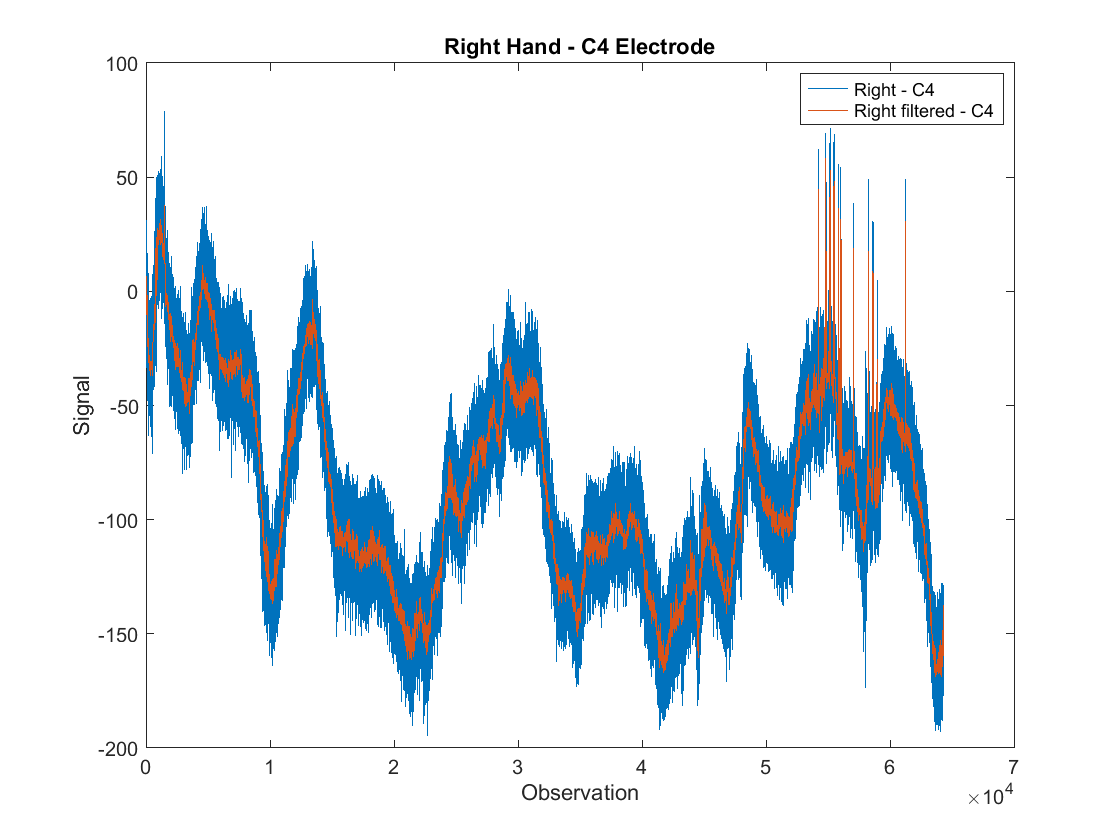

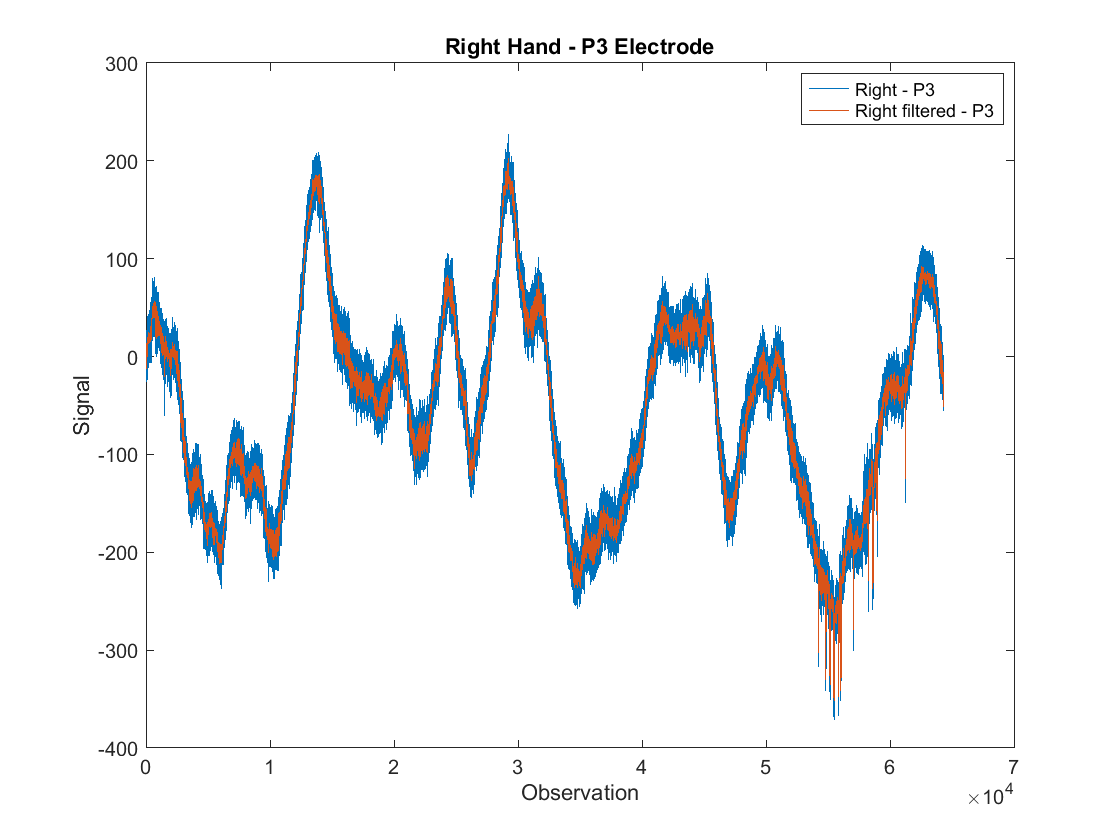

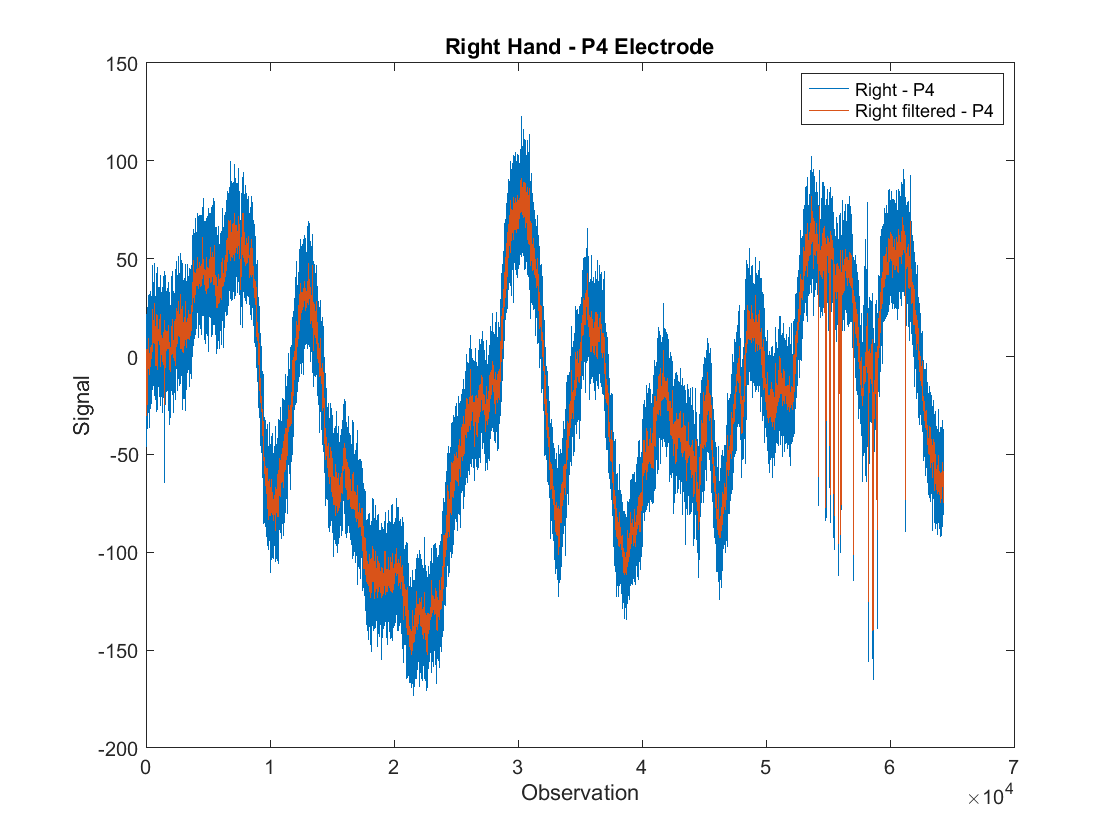

data = filtfilt(filter_spec, right);


for i=1:19
    figure
    plot(1:length(right(:, i)), right(:, i), 1:length(data(:,i)), data(:, i))
    xlabel("Observation")
    ylabel("Signal")
    legend(sprintf("Right - %s", electrodes(i)), sprintf("Right filtered - %s", electrodes(i)))
    title(sprintf("Right Hand - %s Electrode", electrodes(i)))
end

coeff= pcamat(left')

Calculating covariance...
Dimension not reduced.
Selected [ 19 ] dimensions.
Smallest remaining (non-zero) eigenvalue [ 6.58489 ]
Largest remaining (non-zero) eigenvalue [ 35877.1 ]
Sum of removed eigenvalues [ 0 ]
[ 100 ] % of (non-zero) eigenvalues retained.


coeff =    -0.0001   -0.0389    0.1248    0.0045    0.2461   -0.1127   -0.0245   -0.2114   -0.0644    0.6976    0.2422   -0.0787   -0.0957    0.3250    0.0842   -0.3023    0.2634    0.1085   -0.1192
    0.0031    0.1455   -0.1997   -0.0272    0.1326   -0.0050    0.2903    0.6447    0.3018    0.1661   -0.1920   -0.3426    0.1141    0.2558    0.0251    0.1458    0.1437    0.1027    0.1277
    0.0001    0.0092   -0.0252   -0.1391    0.3722    0.2239   -0.3149   -0.1249   -0.4237   -0.1641   -0.3514   -0.4645    0.0668    0.2754   -0.0195   -0.0101   -0.2128    0.0378   -0.0572
   -0.0006   -0.1018    0.0095   -0.0223   -0.0614   -0.0555   -0.4054    0.4641   -0.1734   -0.1691    0.5859    0.0540   -0.1435    0.2569    0.1325   -0.0529   -0.1953    0.1112    0.2002
   -0.7059   -0.0270   -0.1083   -0.0809   -0.3964   -0.2723   -0.1962    0.1098   -0.2177    0.2271   -0.2411   -0.0926   -0.1176   -0.0942    0.0225    0.0756    0.0265    0.0117   -0.0740
   -0.7082    0.0441    0.1126    0.0

## Q2

load("Q2.mat")

% 10 days
% every 3 hours
% -1 because start at 0
% start at 8am
m = 360/24; %m is the multiplier for the degrees
time = (0:10 * 24/3 - 1) * 3 * m + 8 * m;
norm_time = time' / 360;

g1 = goat(:, 1);
g2 = goat(:, 2);
g3 = goat(:, 3);
g4 = goat(:, 4);
g5 = goat(:, 5);
g6 = goat(:, 6);

cosinor(norm_time, g1, 2*pi, 0.05)

The zero amplitude test is less than 0.05 showing the data is significant and that the model is well suited to the data.

cosinor(norm_time, g2, 2*pi, 0.05)

The zero amplitude test is less than 0.05 showing the data is significant and that the model is well suited to the data.

cosinor(norm_time, g3, 2*pi, 0.05)

The zero amplitude test is less than 0.05 showing the data is significant and that the model is well suited to the data.

cosinor(norm_time, g4, 2*pi, 0.05)

The p value is greater than 0.05 therefore the model is not significant and is not a good fit for the data.

cosinor(norm_time, g5, 2*pi, 0.05)

The zero amplitude test is less than 0.05 showing the data is significant and that the model is well suited to the data.

cosinor(norm_time, g6, 2*pi, 0.05)

The zero amplitude test is less than 0.05 showing the data is significant and that the model is well suited to the data.

anova1(goat)

The null hypothesis is that there is no difference between groups. The alternative hypothesis is that there is a significant difference between groups. The p value is greater than 0.05 therefore, accept the null hypothesis as the difference betwee